# Introduction to MATLAB

## Example: Explore storm events and predict costs

The goal of this case study is to explore storm events in various locations in the United States and analyze the frequency and damage costs associated with different types of events. In addition, explore and identify the most costly events and predict the damage costs of events, based on historical data from 1980 - 2020.

The files are freely available from the [National Oceanic and Atomospheric Administration](http://www.noaa.gov/) (NOAA): [https://www1.ncdc.noaa.gov/pub/data/swdi/stormevents/csvfiles/](https://www1.ncdc.noaa.gov/pub/data/swdi/stormevents/csvfiles/)

You can use the script [`GetStormEventData.mlx`](matlab:open('./Helpers/GetStormEventData.mlx')) to download and unzip the files. (Note, this may take some time. Choose fewer files for convenience)

## MATLAB path

To run our files, we need to make sure they are visible on the 'path' You can access files in your current folder, but other directories may need to be added to the path. There are functions, right click on the directory, or through the dialogue menu on the toolstrip.

- [https://mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html](https://uk.mathworks.com/help/matlab/matlab_env/what-is-the-matlab-search-path.html)

- [https://mathworks.com/help/matlab/matlab_env/add-remove-or-reorder-folders-on-the-search-path.html](https://uk.mathworks.com/help/matlab/matlab_env/add-remove-or-reorder-folders-on-the-search-path.html)

Here we use a [MATLAB Project](https://mathworks.com/help/matlab/projects.html) to check for files and add the appropriate directories to the path, which is useful for sharing.

Open [WeatherEvents.prj ](matlab:open('./WeatherEvents.prj'))if you havent already to add the remaining code to the path.

## Import data

Start with one file to explore the data. A subset of the data using fewer columns than the original file has been included for simplicity, `subset2020.csv. `

- Double click on `subset2020.csv` in the Current Folder Browser

- Use the Import Tool to adjust data types and import the data

- Generate a script or function to repeat the steps taken in the app 

- Save it as `importfile.m` (in the `Helpers` directory)

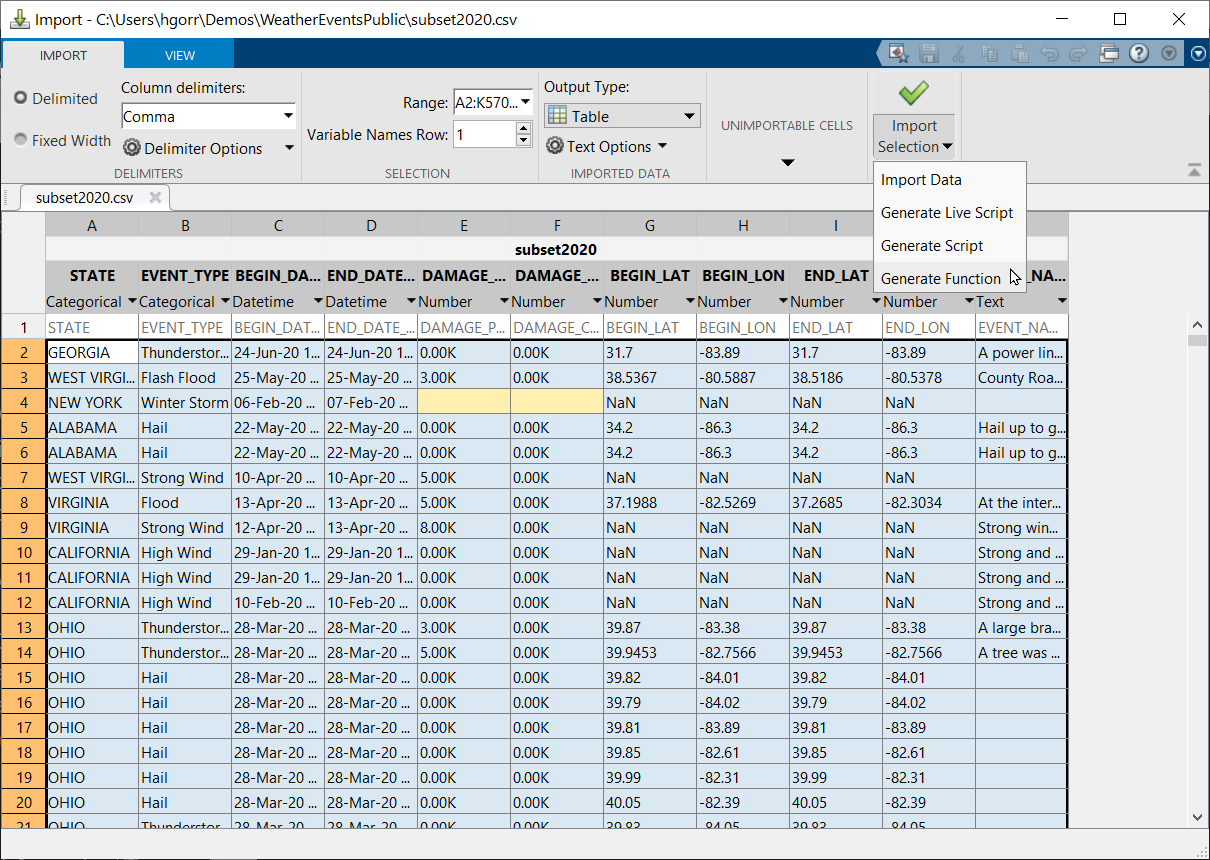

Now, we can use the function created to read the subset of data.

subset2020 = importfile("subset2020.csv");

## Explore subset

Use the tools within the Live Script to explore the data.

subset2020

subset2020 = 57001×11 table
        STATE           EVENT_TYPE         BEGIN_DATE_TIME        END_DATE_TIME       DAMAGE_PROPERTY    DAMAGE_CROPS    BEGIN_LAT    BEGIN_LON    END_LAT    END_LON                                                                                                                                                    EVENT_NARRATIVE                                                                                                                                                
    _____________    _________________    __________________    __________________    _______________    ____________    _________    _________    _______    <

The following code automatically updates when interacting with the table in the Live Script.

subset2020 = sortrows(subset2020,'BEGIN_DATE_TIME');
subset2020 = subset2020(subset2020.DAMAGE_PROPERTY >= 1 | ismissing(subset2020.DAMAGE_PROPERTY),:);

Note the indexing statement to extract data by condition. See the [ReferencingDataInMATLAB.mlx](matlab:open('./Helpers\ReferencingDataInMATLAB.mlx')) for overview of indexing in general and based on condition.

Explore visualizations using the Plots tab. Double click on the variable in the workspace to select different columns and explore types of plots. 

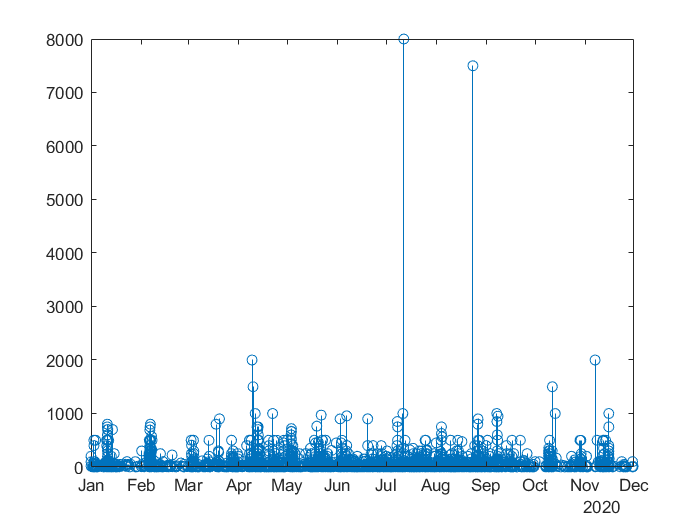

stem(subset2020.BEGIN_DATE_TIME,subset2020.DAMAGE_PROPERTY)

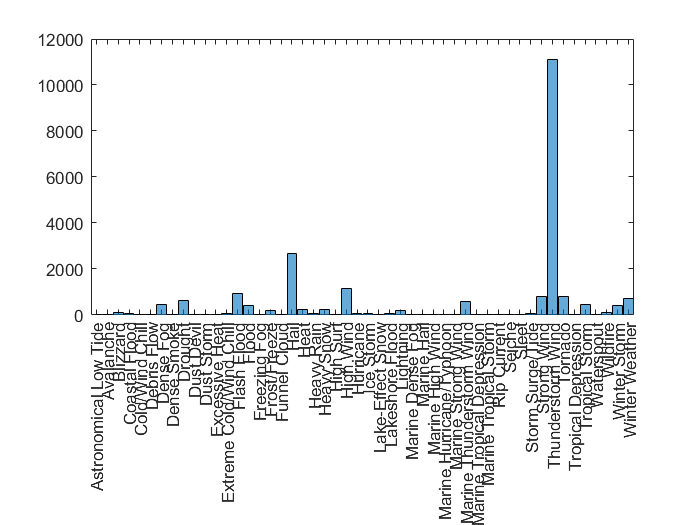

histogram(subset2020.EVENT_TYPE)

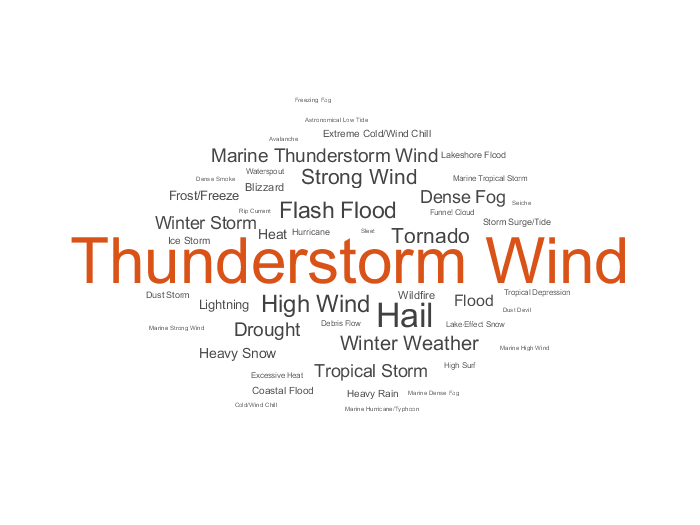

wordcloud(subset2020.EVENT_TYPE);

The plotting code automatically echoes in the command window. You can use this output to create a script (like this one!) to repeat your work. Select the code in the Command History, then right click and select 'Create Live Script'. You can examine the toolstrip for the many options for creating and running code sections, plus rich text, equations and more. 

See the documentation for more on Live Scripts [https://mathworks.com/help/matlab/matlab_prog/create-live-scripts.html](https://uk.mathworks.com/help/matlab/matlab_prog/create-live-scripts.html)

Plot the events on a map.

geobubble(subset2020.BEGIN_LAT,subset2020.BEGIN_LON,...     % the ellipses indicate continuing on the next line
    subset2020.DAMAGE_PROPERTY,subset2020.EVENT_TYPE);

You can interact with the plot and outputs in a Live Script. Zoom and pan to a location of interest and add a legend and title. Note that the code is automatically updated.

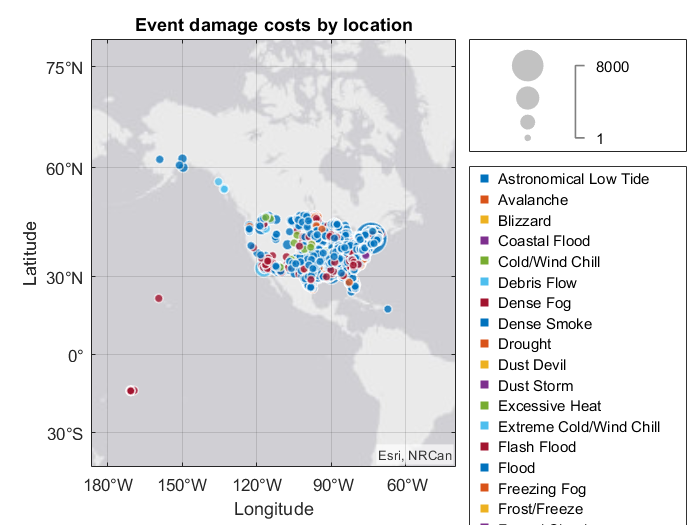

legend
geolimits([-17 70],[-186.8 -39.6])          % limits automatically updated based on zoom/pan
title("Event damage costs by location")

Visualize this in a different way (the Plots tab is great for exploring various options for your data)

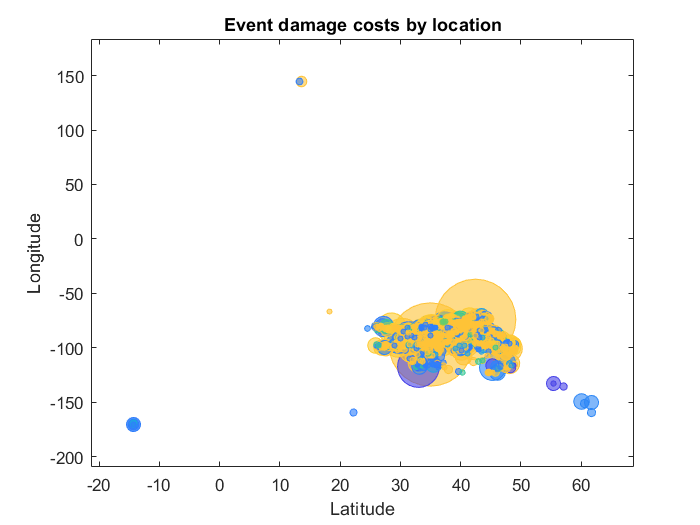

bubblechart(subset2020.BEGIN_LAT,subset2020.BEGIN_LON,...
    subset2020.DAMAGE_PROPERTY,subset2020.EVENT_TYPE);
xlabel("Latitude"); ylabel("Longitude")
title("Event damage costs by location")

See the documentation for the many options for these charts. You can use the search bar or the (?) on the desktop or from the Live Function hints.

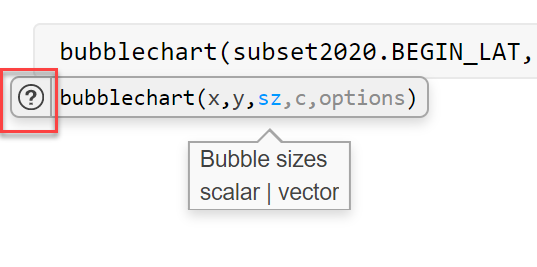

For info and examples on all possible visualizations in MATLAB, see [https://mathworks.com/help/matlab/graphics.html](https://uk.mathworks.com/help/matlab/graphics.html)

## Represent data in MATLAB

Now let's examine the data by different data types in the table.

 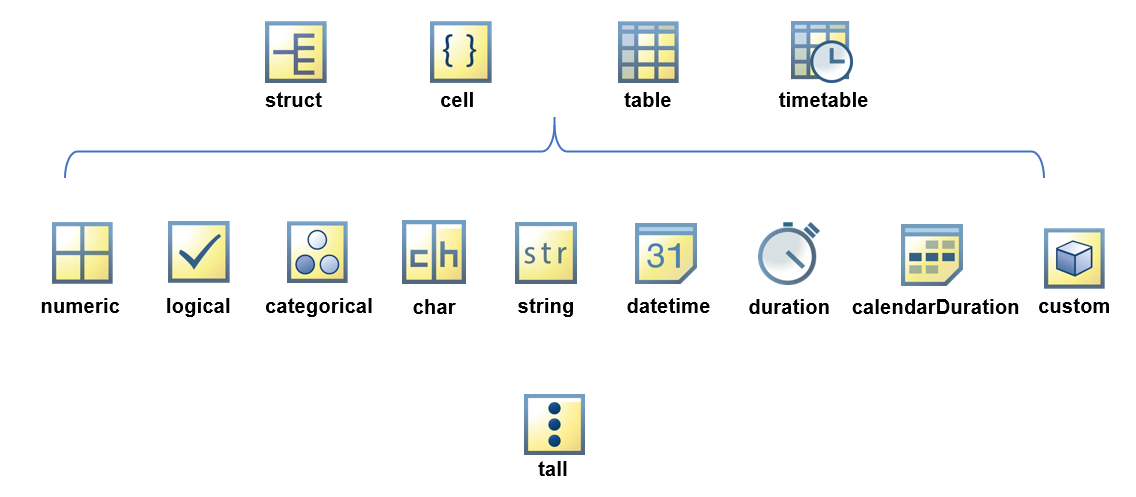

[https://www.mathworks.com/help/matlab/data-types.html](https://www.mathworks.com/help/matlab/data-types.html)

Let's include data from previous years to get a larger subset. 

First, we'll clear the workspace to start fresh (save variables first if you want to retain the data!)

clear 

Load the data from more years. See the script `AccessStormEventData.mlx` which uses a [datastore](https://mathworks.com/help/matlab/ref/datastore.html) to read the data from 1980-2021.

load rawData.mat

## Select data of interest

Select, reorganize the data, update variable names, etc. using [`table`](https://mathworks.com/help/matlab/tables.html) and [`timetable`](https://mathworks.com/help/matlab/ref/timetable.html) functions.

SelectRearrangeData;

## Clean data by type

### Explore timestamps and determine storm durations

data.storm_duration = data.end_timestamp - data.begin_timestamp;

maxDur = max(data.storm_duration);
maxDays = days(maxDur)

maxDays = 30.9993

Use script provided to process further and visualize

PreprocessByTime;

tmin = datetime
   01-Jan-2017 00:00:00

tmax = datetime
   30-Nov-2020 23:00:00

maxNumDays = 30.9993

avgDur = duration
   28:22:47

medDur = duration
   00:06:00

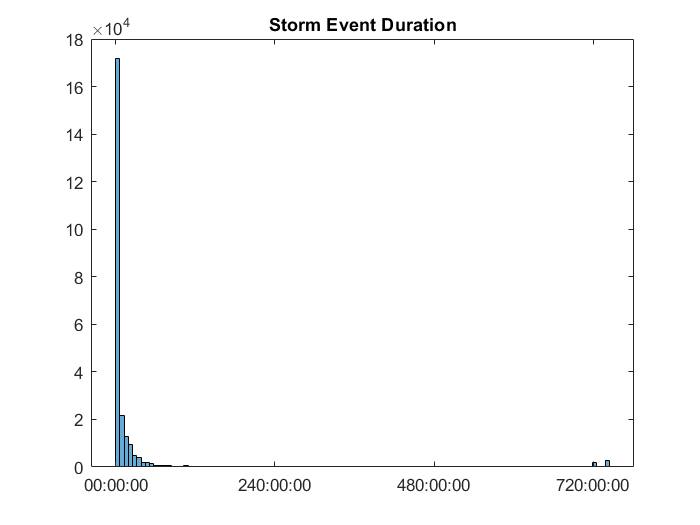

histogram(data.storm_duration)
title("Storm Event Duration")

The longest storm(s) lasted for a month! Examine these storms.

[maxDur,idx] = maxk(data.storm_duration,10);
longestStormDur = data(idx,:)

longestStormDur = 10×10 timetable
            Time                state        event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                                                                         event_narrative                                                                                                                                          storm_duration
    ____________________    _____________    __________    _______________    ____________    _________    _________    _______    _______    _________________________________

### Combine similar storm categories

Visualize the event frequency (use the helper function `bigFigure` to see the many categories)

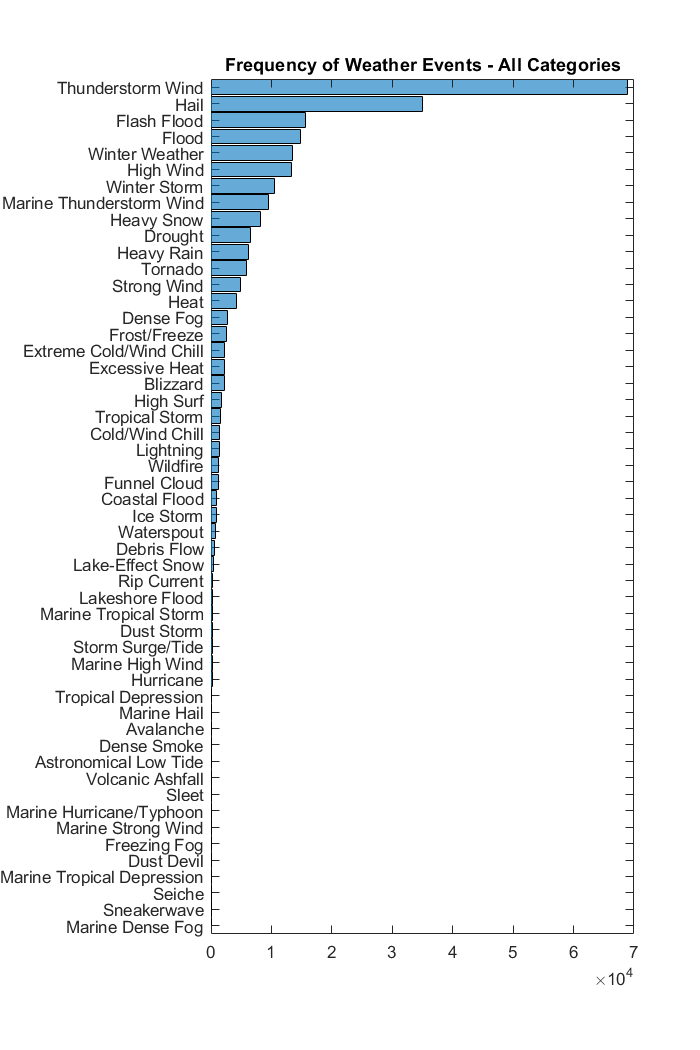

bigFigure("tall");
histogram(data.event_type,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - All Categories")

Combine and update some of the categories.

data.event_type = mergecats(data.event_type,["Strong Wind","High Wind"],"High Wind");

Repeat this for other categories using the helper function.

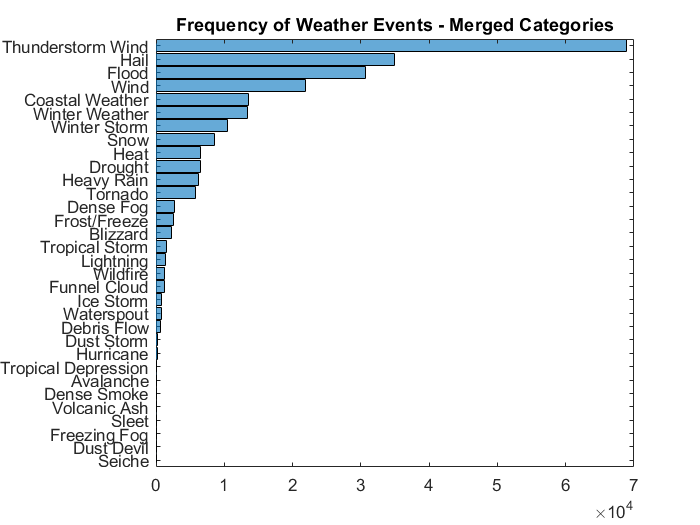

data = PreprocessCategories(data);   
figure
histogram(data.weathercats,"Orientation","horizontal",...
    "DisplayOrder","ascend")
title("Frequency of Weather Events - Merged Categories")

### Clean textual data

Examine some random rows in the table to explore textual data.

datasample(data(:,vartype("string")),10)

ans = 10×7 timetable
            Time            damage_property    damage_crops    begin_lat    begin_lon      end_lat      end_lon                                                                          event_narrative                                                                     
    ____________________    _______________    ____________    _________    __________    _________    __________    ________________________________________________________________________________________________________________________________________________________
    02-Jan-2017 14:09:00        "5.00K"          "0.00K"       "32.2685"    "-90.2301"    "32.2685"    "-90.2301"    "A large tree was blown down on M

Explore damage costs including "M" (millions). 

idxM = contains(data.damage_property,"M"); 
data(idxM,:)

ans = 1505×11 timetable
            Time              state          event_type        damage_property    damage_crops    begin_lat     begin_lon      end_lat       end_lon                                                                                                                                                                                                                                                                                                                                                                                                                                                            event_narrative                                                                                                                                                                                                       

Convert the damage costs containing "K" and "M" with the correct units using the helper function, `PreprocessStrings.mlx`. 

See the many functions for parsing text here: [https://mathworks.com/help/matlab/characters-and-strings.html](https://mathworks.com/help/matlab/characters-and-strings.html)

data = PreprocessStrings(data);
head(data)

ans = 8×12 timetable
            Time             state      event_type    damage_property    damage_crops    begin_lat    begin_lon    end_lat    end_lon                                                                                                                                         event_narrative                                                                                                                                          storm_duration    weathercats    damage_total
    ____________________    ________    __________    _______________    ____________    _________    _________    _______    _______   

## Explore data 

### Visualize event descriptions

Explore the free text based on event type.

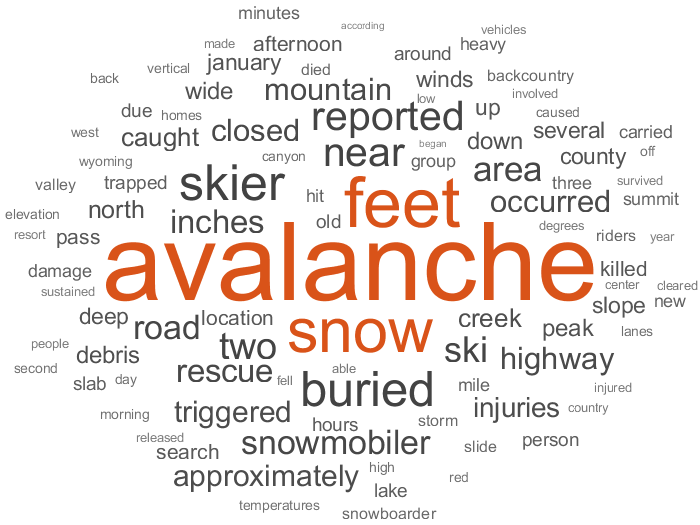

type = types(1);

wordcloud(lower(data.event_narrative(data.event_type == type)));

### Visualize damage of events on a map

Use the size of the bubble as the damage cost.

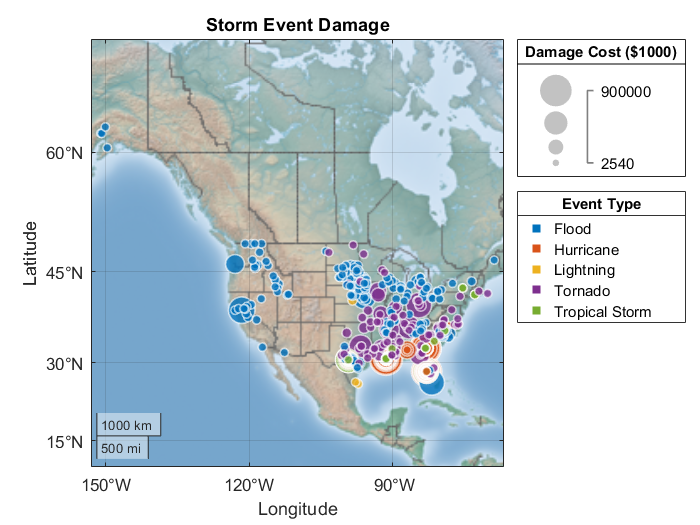

threshold = 2510;
plotEventCostsMap(data,threshold);

### Event frequency by location

Calculate damage costs by group.

damageByEvent = groupsummary(data,"weathercats",...
    ["mean","std","median"],"damage_total") 

damageByEvent = 32×5 table
      weathercats      GroupCount    mean_damage_total    std_damage_total    median_damage_total
    _______________    __________    _________________    ________________    ___________________
    Avalanche              106              2.5798             20.824                  0         
    Blizzard              2282              8.5473             102.43                  0         
    Coastal Weather      13560              171.87             7842.6                  0         
    Debris Flow            596              1153.8              25285                  0         
    Dense Fog             2779             0.76563             7.9844                  0         
    Dense Smoke             77                   0                  0                  0         
    Drought        

Visualize the top events by cost.

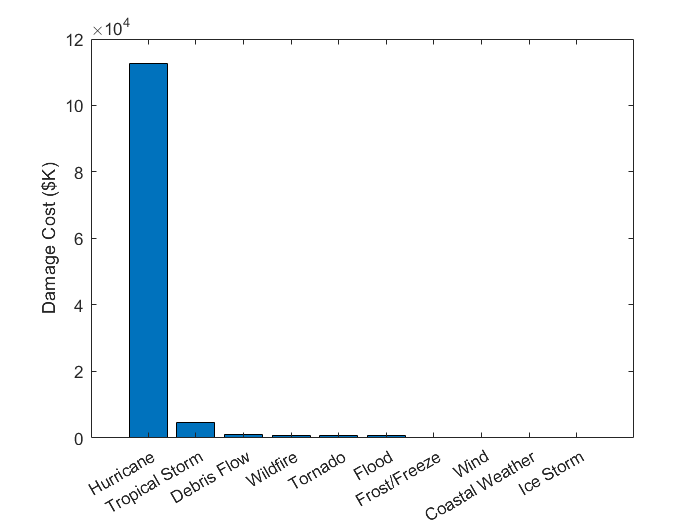

topdamage = topkrows(damageByEvent,10,"mean_damage_total");

bar(topdamage.mean_damage_total)
xticklabels(string(topdamage.weathercats))
% xtickangle(90)
ylabel("Damage Cost ($K)")

Include location

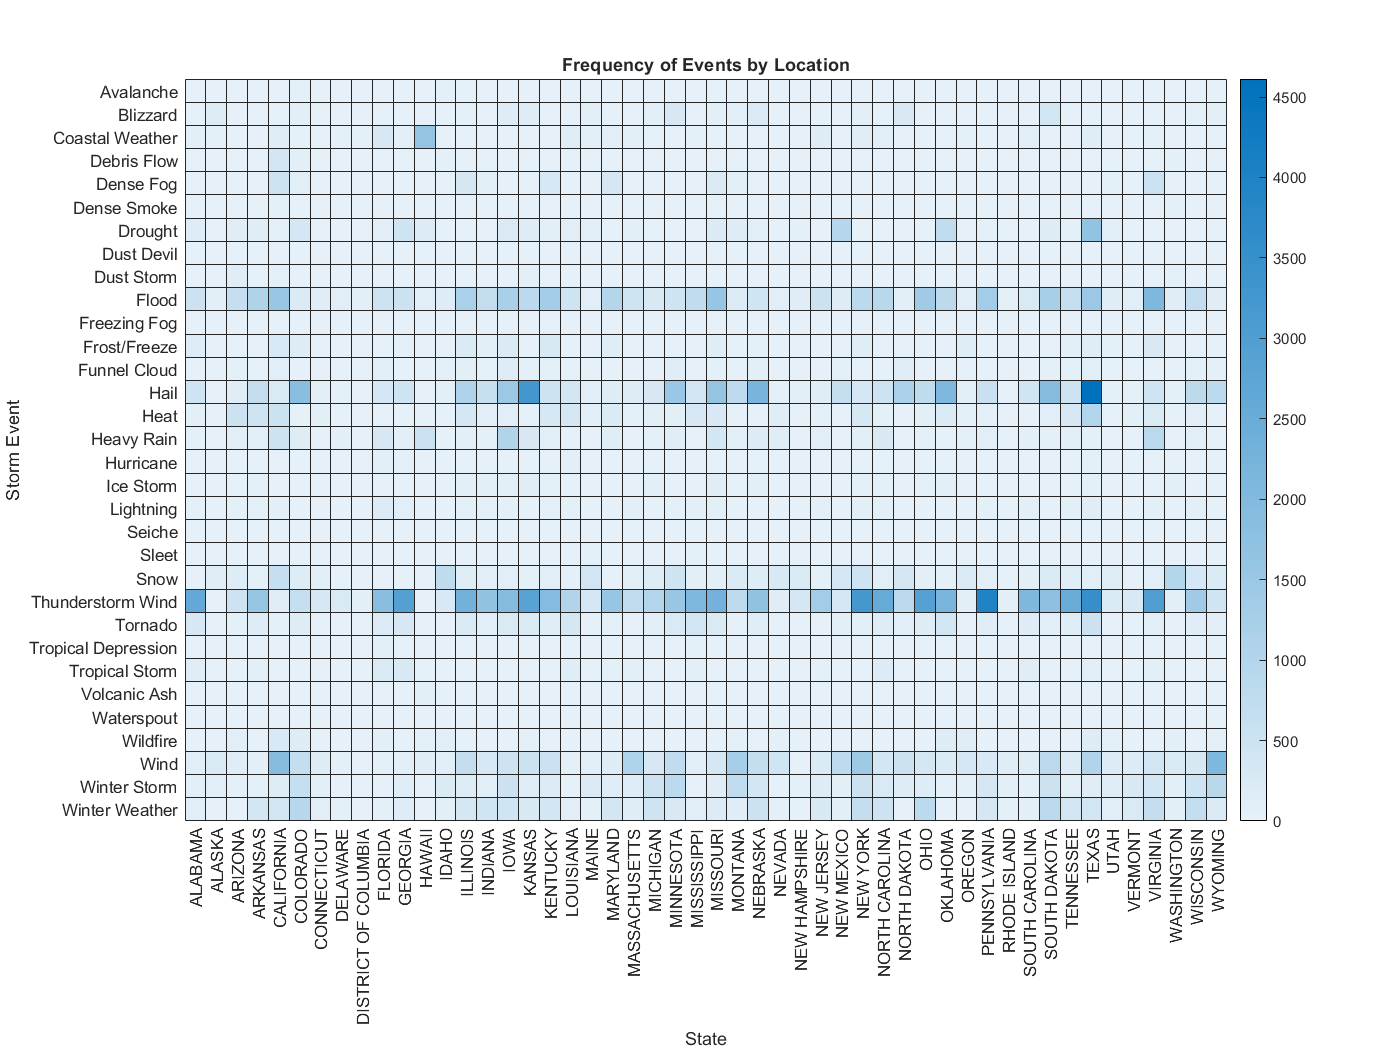

bigFigure; 
heatmap(data,"state","weathercats");        
xlabel("State")                                     
ylabel("Storm Event")
title("Frequency of Events by Location")

### Compare damage cost by event and location

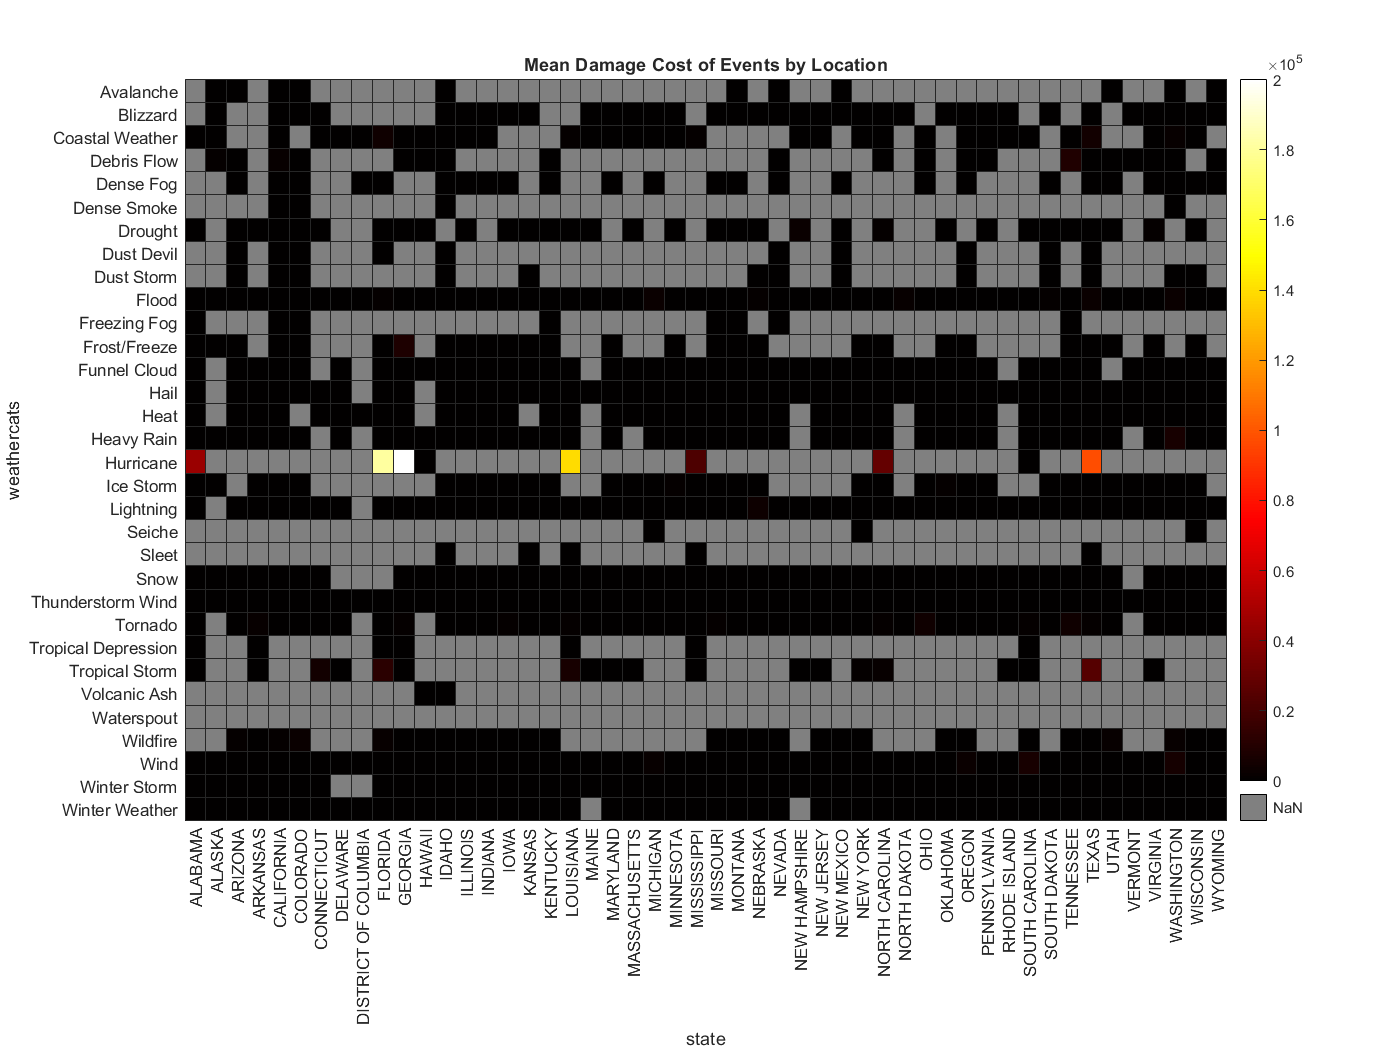

h = heatmap(data,"state","weathercats","ColorVariable","damage_total");        
h.Colormap = hot;
h.MissingDataColor = [0.5 0.5 0.5];
title("Mean Damage Cost of Events by Location")

Explore damage costs with several visualizations using the helper function defined below.

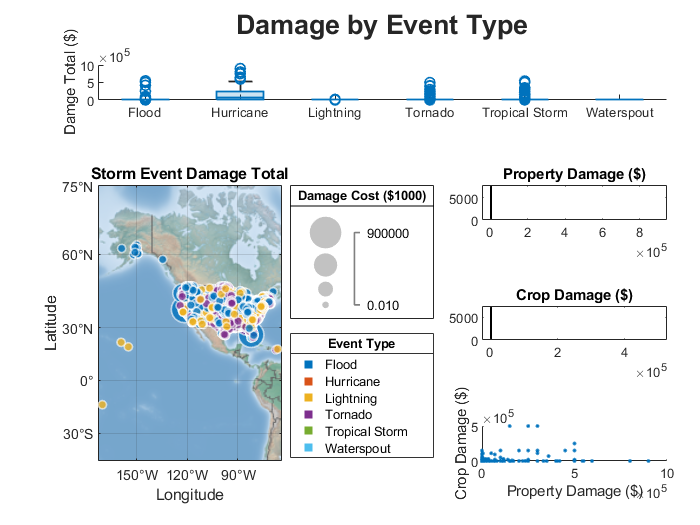

plotEventCosts(data)

We will also leave these alone for the moment and revisit strategies during modeling. Some events are just way more expensive than others!

## Save the prepped data

We could write results to file types of choice (.csv, xls, ..) or save as a `.mat` file for future use in MATLAB.

% save PreprocessedData\preprocessedData2017_2020.mat

## Scale analysis to all years

Repeat this analysis for data from all years since 1980. See [PreprocessAllData.mlx](matlab:open('./PreprocessAllData.mlx')) for details.

## Predict damage costs

Follow the script `PredictDamageCosts.mlx` to build a machine learning model (using the Regression Learner app) to predict the costs of events.

edit PredictDamageCosts

## Create Web App

Now this model can be used in an app to predict cost based on these variables. See [CreateWebApplication.mlx](matlab:open('./CreateWebApplication.mlx')) for more.

EventDamageCosts

**Helper functions**

function plotEventCostsMap(data,threshold)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > threshold;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
x = FillMissingLatLon(x);
figure
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
end

function data = FillMissingLatLon(data)
stateLatLon = struct2table(shaperead("usastatehi"));
idx = find(ismissing(data.begin_lat) & ismissing(data.begin_lon) & ~ismissing(data.state) & ...
    ismember(string(data.weathercats),["Tropical Storm","Hurricane",...
    "Waterspout"]));
for ii = 1:length(idx)
    sidx = lower(stateLatLon.Name) == lower(string(data.state(idx(ii))));
    data.begin_lat(idx(ii)) = stateLatLon.LabelLat(sidx);
    data.begin_lon(idx(ii)) = stateLatLon.LabelLon(sidx);
end
end

function plotEventCosts(data)
ev = ["Flood","Lightning","Tropical Storm","Hurricane",...
    "Waterspout","Tornado"];
idx = ismember(string(data.event_type),ev) & ...
    data.damage_total > 0;
x = data(idx ,:);
x.weathercats = removecats(x.weathercats);
warning("off","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
% Create figure
figure
t = tiledlayout(4,2,"TileSpacing","compact","Padding","compact");  %#ok
nexttile([1 2])
% boxplot(x.damage_total,x.event_type)
grps = removecats(x.event_type);
boxchart(grps,x.damage_total)
ylabel("Damge Total ($)")
nexttile(3,[3 1])
gb = geobubble(x,"begin_lat","begin_lon",...
    "SizeVariable","damage_total","ColorVariable","weathercats");
gb.Title = "Storm Event Damage Total";
gb.SizeLegendTitle = "Damage Cost ($1000)";
gb.ColorLegendTitle = "Event Type";
gb.Basemap = "colorterrain";
nexttile
histogram(x.damage_property)
title("Property Damage ($)")
nexttile
histogram(x.damage_crops)
title("Crop Damage ($)")
nexttile
scatter(x.damage_property,x.damage_crops,".");
xlabel("Property Damage ($)"); ylabel("Crop Damage ($)")
sgtitle("Damage by Event Type","FontWeight","bold","FontSize",16)
warning("on","MATLAB:handle_graphics:Layout:NoPositionSetInTiledChartLayout")
end

*Copyright 2018 - 2021 The MathWorks, Inc.*